
%#ok<*CLALL>

clear all;clc 

% Sim settings. 
maxSpeed = 1E-1; 
timeStep = 4; 

% Initial states. 
initialStates = [-1; 0; 1; 0; maxSpeed; 0; 0; maxSpeed]; 

% Position constraints. 
areaBounds = [-1; 1; -1; 1]*50; 

% Position constraint test. 
% areaBounds(2) = -0.5; 

% TPBVP test time span input. 
tspan = 0 : 1E-2 : timeStep; 

% Initial guess. 
% guess = [ ...
%     initialStates; ...
%     (initialStates(1)-initialStates(3)); ...
%     (initialStates(2)-initialStates(4)); ...
%     -(initialStates(1)-initialStates(3)); ...
%     -(initialStates(2)-initialStates(4)); ...
%     zeros(4, 1)]; 
guess = 1E-1*ones(16, 1); 
guess(1:8) = [ ...
    initialStates(3); ...
    initialStates(4); ...
    initialStates(3)+timeStep*initialStates(7); 
    initialStates(4)+timeStep*initialStates(8); ...
    initialStates(7); ...
    initialStates(8); ...
    initialStates(7); ...
    initialStates(8)]; 
guess(9) = (guess(1)-guess(3)); 
guess(10) = (guess(2)-guess(4)); 
guess(11) = -(guess(1)-guess(3)); 
guess(12) = -(guess(2)-guess(4)); 
disp(guess); 

    1.0000
         0
    1.0000
    0.4000
         0
    0.1000
         0
    0.1000
         0
   -0.4000
         0
    0.4000
    0.1000
    0.1000
    0.1000
    0.1000



solGuess = bvpinit(tspan, guess); 
options = bvpset("Stats", "on"); 
sol = bvp4c( ...
    @(t, y) eqns(t, y, maxSpeed, areaBounds), ...
    @(y_a, y_b) boundaryConditions(y_a, y_b, initialStates), ...
    solGuess, options); 

The solution was obtained on a mesh of 401 points.
The maximum residual is  5.203e-06. 
There were 24102 calls to the ODE function. 
There were 141 calls to the BC function. 


solGuess = bvpinit(tspan, sol.y(:, end)); 
sol = bvp4c( ...
    @(t, y) eqns(t, y, maxSpeed, areaBounds), ...
    @(y_a, y_b) boundaryConditions(y_a, y_b, initialStates), ...
    solGuess, options); 

The solution was obtained on a mesh of 401 points.
The maximum residual is  2.621e-12. 
There were 8835 calls to the ODE function. 
There were 48 calls to the BC function. 


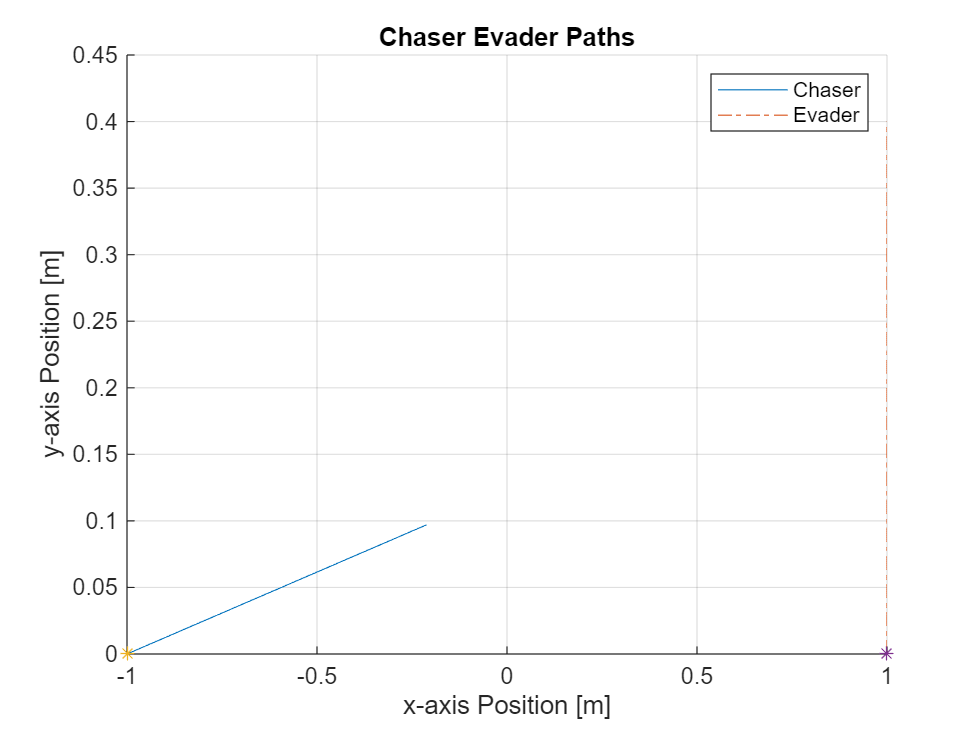

tspan = sol.x; 
y = sol.y; 
chaserPath = y(1:2, :); 
evaderPath = y(3:4, :); 

clf; 
hold on; 
grid on; 
plot(chaserPath(1, :), chaserPath(2, :)); 
plot(evaderPath(1, :), evaderPath(2, :), "-."); 
plot(chaserPath(1, 1), chaserPath(2, 1), "*"); 
plot(evaderPath(1, 1), evaderPath(2, 1), "*"); 
title("Chaser Evader Paths"); 
xlabel("x-axis Position [m]"); 
ylabel("y-axis Position [m]"); 
legend("Chaser", "Evader"); 
% axis([-2 1 -1 1.6]); 
hold off;  

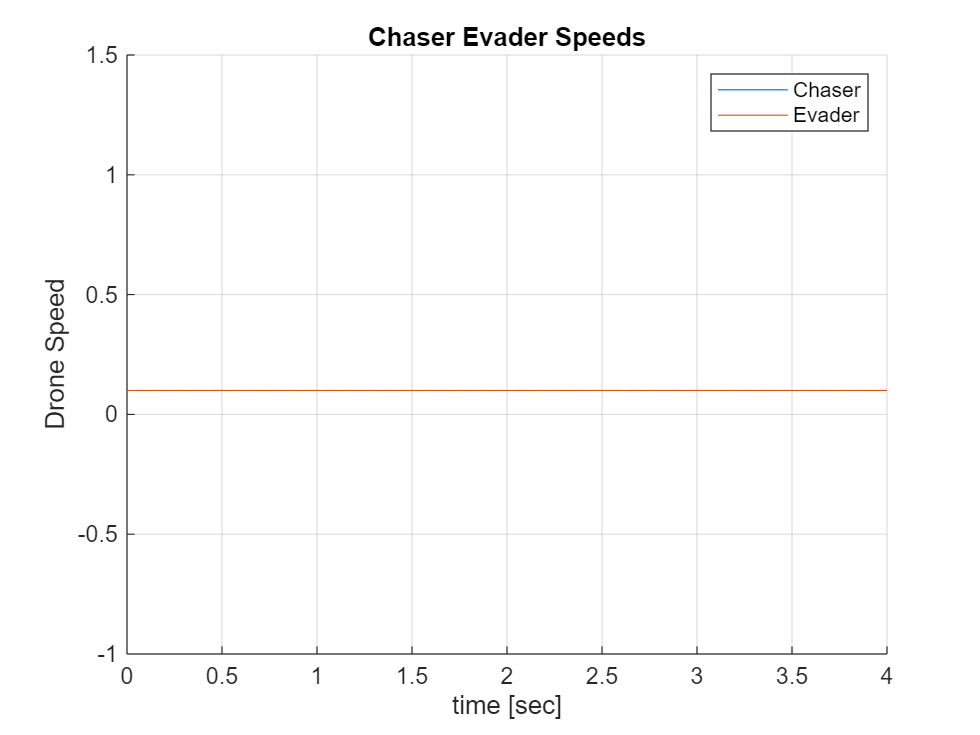

clf; 
hold on; 
grid on; 
plot(tspan, sqrt(y(5, :).^2+y(6, :).^2)); 
plot(tspan, sqrt(y(7, :).^2+y(8, :).^2)); 
title("Chaser Evader Speeds"); 
xlabel("time [sec]"); 
ylabel("Drone Speed"); 
legend("Chaser", "Evader"); 
hold off; 

% Differential equations. 
function dydt = eqns(~, y, maxSpeed, areaBnds)
    % % Equivalence threshold. 
    % eps = 1E-3; 
    % 
    % % Optimal Control. 
    % u = (abs(y(9:10))>eps) .* -sign(y(9:10))*maxSpeed; 
    % Optimal Control. 
    theta = atan2(y(10), y(9)) + pi; 
    u = maxSpeed*[cos(theta); sin(theta)]; 
    
    % Position and velocity constraints. 
    mu = max([ ...
        areaBnds(1)-y(1); ...
        y(1)-areaBnds(2); ...
        areaBnds(3)-y(2); ...
        y(2)-areaBnds(4)], 0); 
    if ~sum(mu == 0, "all")
        disp(mu); 
    end

    A = [zeros(4) eye(4); zeros(4) zeros(4)]; 
    B = [eye(2); zeros(2); zeros(2); zeros(2)]; 

    dydt = [ ...
        A*y(1:8)+B*u; ...
        mu(1)-mu(2); ...
        mu(3)-mu(4); ...
        0; ...
        0; ...
        -y(9:12)]; 
end

% Boundary conditions. 
function retval = boundaryConditions(y_a, y_b, initialStates)
    retval = [ ...
        y_a(1:8)-initialStates; ...
        y_b(9:16) - [ ...
        y_b(1)-y_b(3); ...
        y_b(2)-y_b(4); ...
        -(y_b(1)-y_b(3)); ...
        -(y_b(2)-y_b(4)); ...
        zeros(4, 1)]]; 
end